clear
clc

## Dinámica no lineal

syms x [1 6] real
syms p [1 8] real
syms q [1 3] real
syms tau [3 1] real

grav = 9.81;

m11 = cos(x(2))^2*p(1) + cos(x(2))*cos(x(2) + x(3))*p(2) + sin(x(2) + x(3))*p(3);
m22 = p(1) + 2*cos(x(3))*p(2) + p(3);
m23 = cos(x(3)) * p(2) + p(3);
m32 = cos(x(3)) * p(2) + p(3);
m33 = p(3);

M = [m11 0   0;
    0   m22 m23;
    0   m32 m33];

c11 = -cos(x(2))*sin(x(2))*x(5)*p(1) - 1/2*(cos(x(2))*sin(x(2) + x(3))*(x(5) + x(6)) + sin(x(2))*cos(x(2) + x(3))*x(5))*p(2) + cos(x(2) + x(3))*sin(x(2) + x(3))*(x(5) + x(6))*p(3);
c12 = -cos(x(2))*sin(x(2))*x(4)*p(1) - 1/2*(sin(x(2))*cos(x(2) + x(3)) + cos(x(2))*sin(x(2) + x(3)))*x(4)*p(2) + sin(x(2) + x(3))*cos(x(2) + x(3))*x(4)*p(3);
c13 = -1/2*cos(x(2))*sin(x(2) + x(3))*x(4)*p(2) + cos(x(2) + x(3))*sin(x(2) + x(3))*x(4)*p(3);
c21 = cos(x(2))*sin(x(2))*x(4)*p(1) + 1/2*(sin(x(2))*cos(x(2) + x(3)) + cos(x(2))*sin(x(2) + x(3)))*x(4)*p(2) - sin(x(2) + x(3))*cos(x(2) + x(3))*x(4)*p(3);
c22 = -sin(x(3))*x(6)*p(2);
c23 = -sin(x(3))*(x(5) + x(6))*p(2);
c31 = 1/2*cos(x(2))*sin(x(2) + x(3))*x(4)*p(2) - cos(x(2) + x(3))*sin(x(2) + x(3))*x(4)*p(3);
c32 = sin(x(5))*p(2);
c33 = 0;

C = [c11 c12 c13;
    c21 c22 c23;
    c31 c32 c33];

d1=p(4)*x(4);
d2=p(5)*x(5);
d3=p(6)*x(6);

D=[d1; d2; d3];

g2 = grav*(cos(x(2))*p(7) + cos(x(2) + x(3))*p(8));
g3 = grav*cos(x(2) + x(3))*p(8);

G = [0;
     g2;
     g3];

q_dot = [x(4); x(5); x(6)];

q_ddot = - M \ (C * q_dot + D + G);

f = [q_dot
    q_ddot];

g = [0; 
     0; 
     0; 
     M \ tau];

## Linealización

x0 = [0; pi/4; pi/4; 0; 0; 0];
u = [0; 0; 0];

params = [  0.00349359
            0.00246677
            0.00333632
            0.00076823
            0.03526735
            0.00744473
            0.00449158
            0.01701218
          ];

A = simplify(jacobian(f, x));
B = simplify(jacobian(g, tau));
C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1];
D = [0 0 0;
     0 0 0;
     0 0 0;
     0 0 0;
     0 0 0;
     0 0 0];

A = vpa(subs(A, [x, tau', p], [x0', u', params']))

$$A = \left(\begin{array}{cccccc} 0 & 0 & 0 & 1.0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1.0\\ 0 & 0 & 0 & -0.15113370443123950234114555502466 & 0 & 0\\ 0 & -21.728268435032149377285072128719 & -25.27081136069572343135684141046 & 0 & -13.660705139025574005797462039185 & 4.3913259460439942598459943305992\\ 0 & 83.110104745933255574130417877666 & 82.195168665810217296045288657271 & 0 & 20.802692522524614258072305719709 & -8.9185856831341852707079359230954 \end{array}\right)$$

B = vpa(subs(B, [x, tau', p], [x0', u', params']))

$$B = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 196.72976117990642291731527885136 & 0 & 0\\ 0 & 387.34708275573789629137579691123 & -589.85697883522897436960649090123\\ 0 & -589.85697883522897436960649090123 & 1197.9730202618745278812936677376 \end{array}\right)$$


sys = ss(double(A), double(B), C, D)

sys =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1        0        0        0        1        0        0
   x2        0        0        0        0        1        0
   x3        0        0        0        0        0        1
   x4        0        0        0  -0.1511        0        0
   x5        0   -21.73   -25.27        0   -13.66    4.391
   x6        0    83.11     82.2        0     20.8   -8.919
 
  B = 
           u1      u2      u3
   x1       0       0       0
   x2       0       0       0
   x3       0       0       0
   x4   196.7       0       0
   x5       0   387.3  -589.9
   x6       0  -589.9    1198
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
   y4   0   0   0
   y5   0   0   0
   y6   0 

## Simulación

T = 20;
dt = 0.01;
tspan = 0:dt:T;
u_lin = zeros(length(tspan), 3);
[y, t, x] = lsim(sys, u_lin, tspan, x0);

## Gráficas

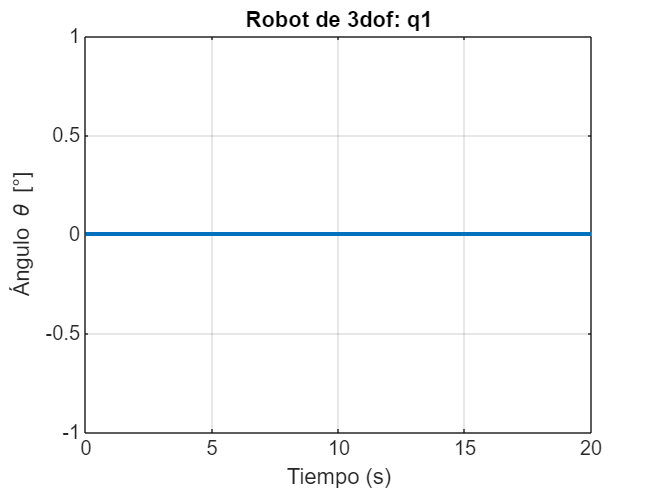

figure;
plot(tspan, y(:,1)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q1');
grid on;

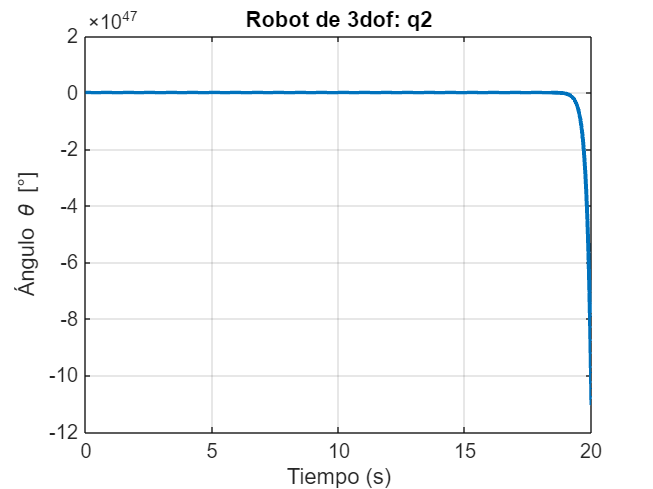


figure;
plot(tspan, y(:,2)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q2');
grid on;

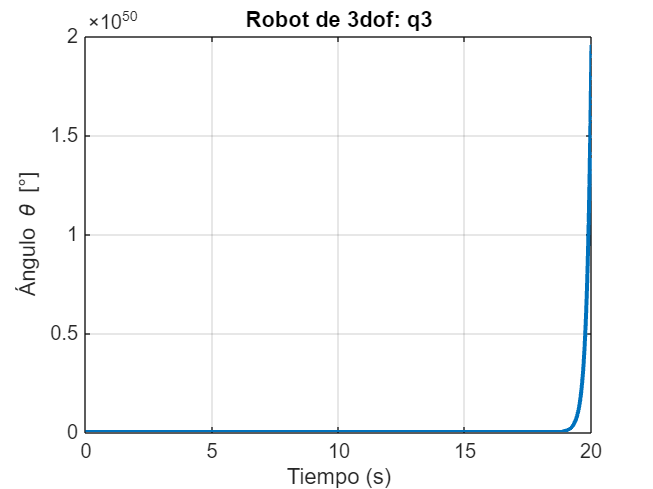


figure;
plot(tspan, y(:,3)*180/pi, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta [°]');
title('Robot de 3dof: q3');
grid on;

## Observabilidad

Ob = obsv(A,C);
disp('Matriz de observabilidad:')

Matriz de observabilidad:


disp(Ob)

   1.0e+07 *

   0.000000100000000                   0                   0                   0                   0                   0
                   0   0.000000100000000                   0                   0                   0                   0
                   0                   0   0.000000100000000                   0                   0                   0
                   0                   0                   0   0.000000100000000                   0                   0
                   0                   0                   0                   0   0.000000100000000                   0
                   0                   0                   0                   0                   0   0.000000100000000
                   0                   0                   0   0.000000100000000                   0                   0
                   0                   0                   0                   0   0.000000100000000                   0
                  


if rank(Ob) == size(A, 1)
    disp('El sistema es observable.')
else
    disp('El sistema no es observable.')
end

El sistema es observable.


## Controlabilidad

Co = ctrb(A,B);
disp('Matriz de controlabilidad:')

Matriz de controlabilidad:


disp(Co)

   1.0e+09 *

                   0                   0                   0   0.000000196729761                   0                   0  -0.000000029732498                   0                   0   0.000000004493583                   0                   0  -0.000000000679132                   0                   0   0.000000000102640                   0                   0
                   0                   0                   0                   0   0.000000387347083  -0.000000589856979                   0  -0.000007881688540   0.000013318552269                   0   0.000172645310328  -0.000300200172266                   0  -0.003836927311578   0.006724452645379                   0   0.085634305966396  -0.150416295718495
                   0                   0                   0                   0  -0.000000589856979   0.000001197973020                   0   0.000013318552269  -0.000022954838390                   0  -0.000299033930074   0.000531230959876                   0   0


if rank(Co) == size(A, 1)
    disp('El sistema es controlable.')
else
    disp('El sistema no es controlable.')
end

El sistema es controlable.


## Matriz de Transferencia

Gs = tf(sys);
disp("Matriz de transferencia:")

Matriz de transferencia:


disp("Numerador:")

Numerador:


disp(Gs.Numerator)

    {[0 0 1.967297611799064e+02]}    {[                                                                                          0]}    {[                                                                                           0]}
    {[                        0]}    {[                     0 0 3.873470827557380e+02 8.643338910548528e+02 -1.693189435738247e+04]}    {[                     0 0 -5.898569788352291e+02 -3.143389435865784e-12 1.820964365382617e+04]}
    {[                        0]}    {[                    0 0 -5.898569788352289e+02 -1.047796478621928e-12 1.937588584645213e+04]}    {[                      0 0 1.197973020261875e+03 4.094542831330794e+03 -2.299319593393941e+04]}
    {[  0 1.967297611799064e+02]}    {[                                                                                          0]}    {[                                                                                           0]}
    {[                        0]}    {[0 3.873470827557358e+02 8.643

disp("Denominador:")

Denominador:


disp(Gs.Denominator)

    {[1 0.151133704431239 0]}    {[                                                                                    1]}    {[                                                                                    1]}
    {[                    1]}    {[1 22.579290822159738 -29.984134378084946 -7.683211800301096e+02 3.143010903686747e+02]}    {[1 22.579290822159738 -29.984134378084946 -7.683211800301096e+02 3.143010903686747e+02]}
    {[                    1]}    {[1 22.579290822159738 -29.984134378084946 -7.683211800301096e+02 3.143010903686747e+02]}    {[1 22.579290822159738 -29.984134378084946 -7.683211800301096e+02 3.143010903686747e+02]}
    {[  1 0.151133704431239]}    {[                                                                                    1]}    {[                                                                                    1]}
    {[                    1]}    {[1 22.579290822159738 -29.984134378084946 -7.683211800301096e+02 3.143010903686747e+02]}    {[1 22.579